# Autocorrelation

clear

idx = [0,3,6,8,10,11,13,15,16,17,20];
formatspec = 'Data/MATLAB_data/Experimental_data_%d.mat';

err = zeros(11,1)

err =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


M = 0.5337

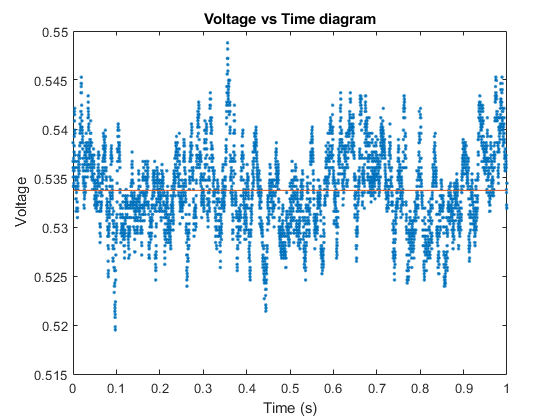

T = 0.0059

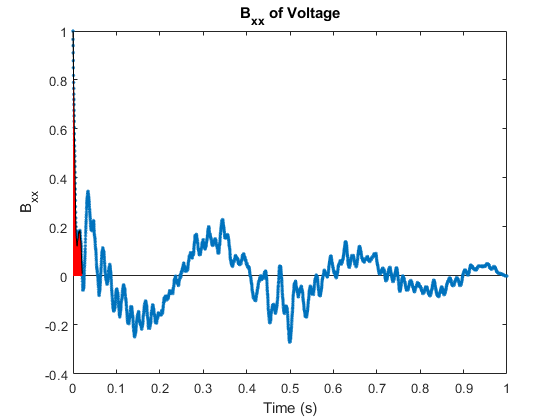

sigma = 0.0029

N = 85.1614

M = 0.5277

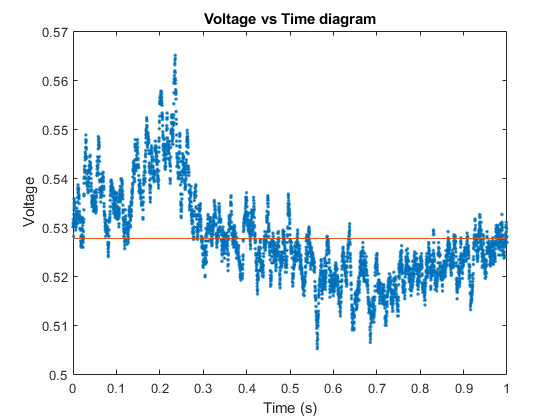

T = 0.1170

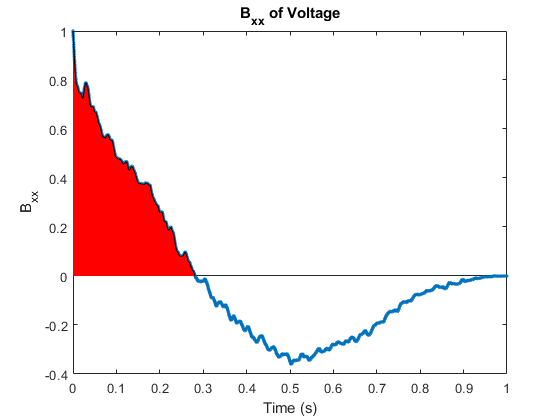

sigma = 0.0067

N = 4.2725

M = 0.5318

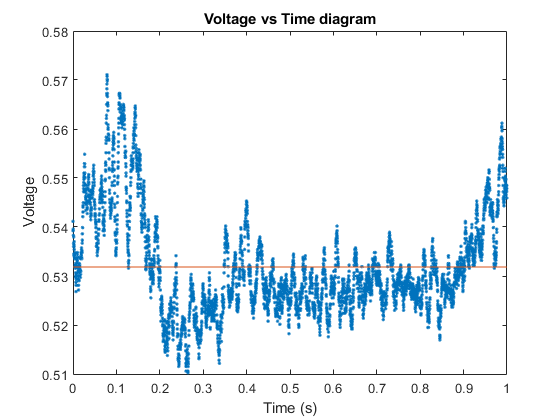

T = 0.0457

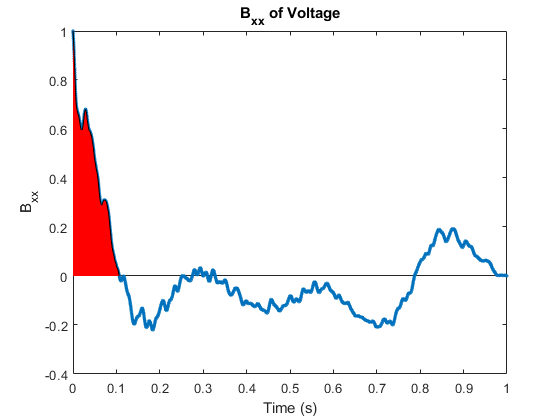

sigma = 0.0073

N = 10.9497

M = 0.5489

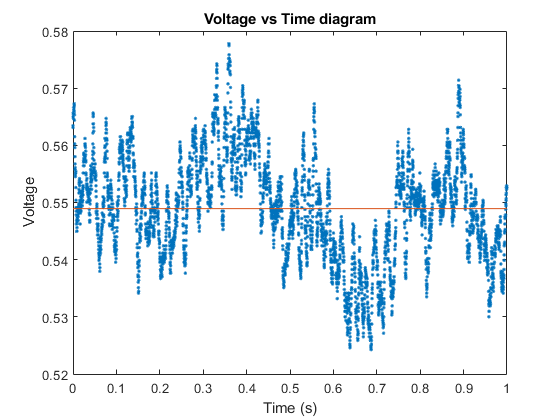

T = 0.0343

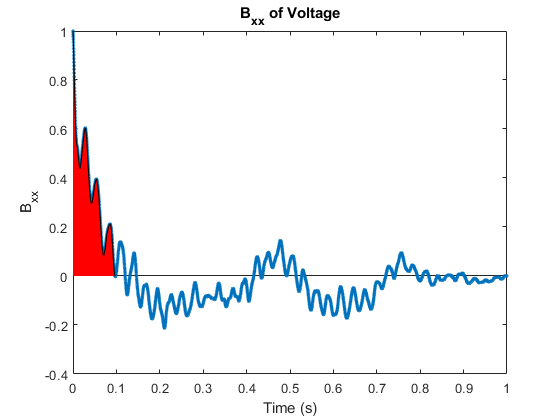

sigma = 0.0065

N = 14.5563

M = 0.5511

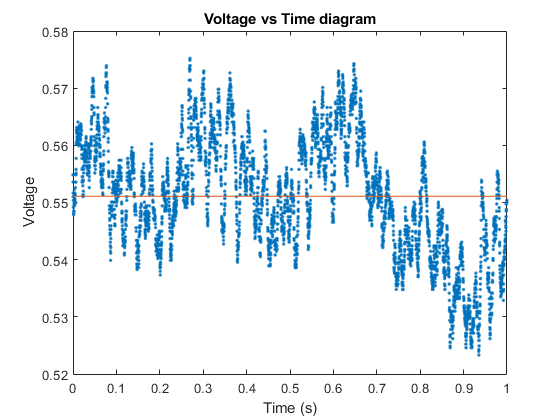

T = 0.0461

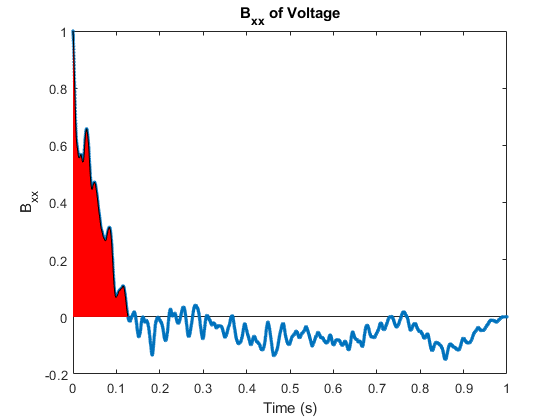

sigma = 0.0073

N = 10.8563

M = 0.5562

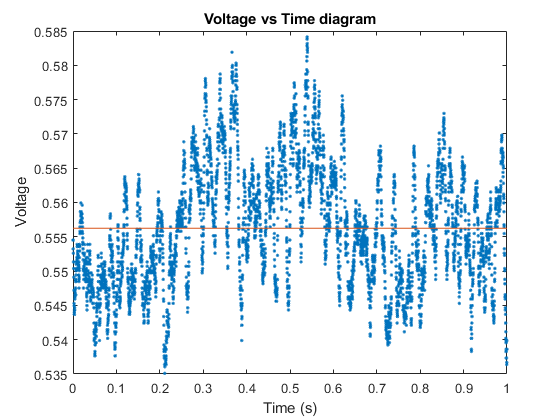

T = 0.0276

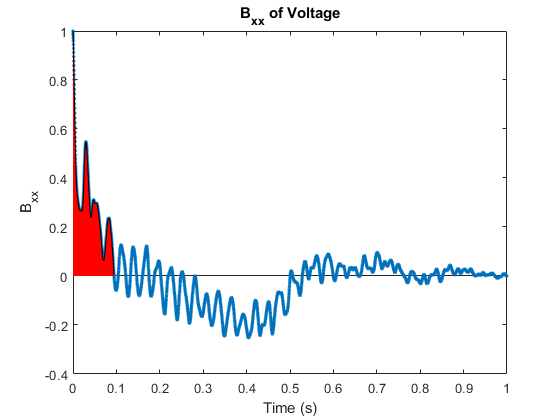

sigma = 0.0062

N = 18.1101

M = 0.5541

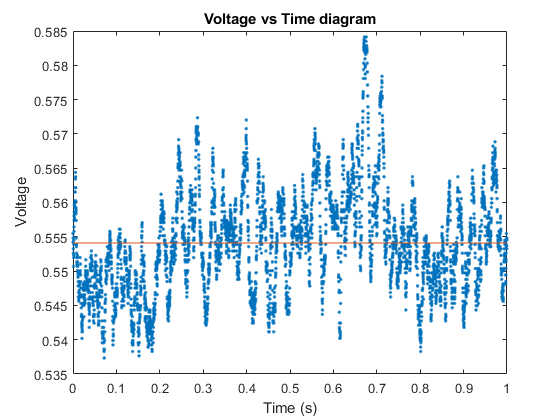

T = 0.0193

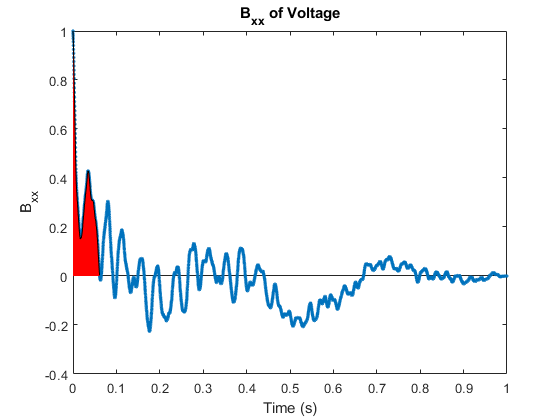

sigma = 0.0054

N = 25.9300

M = 0.5570

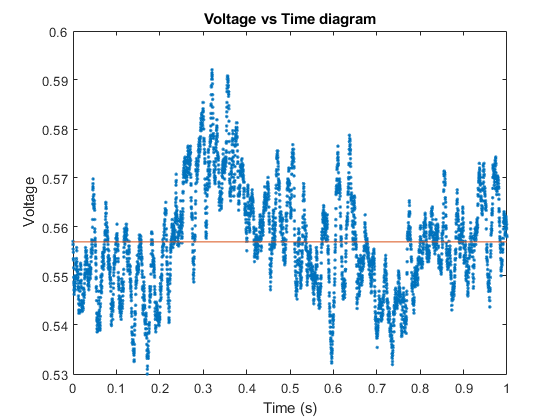

T = 0.0404

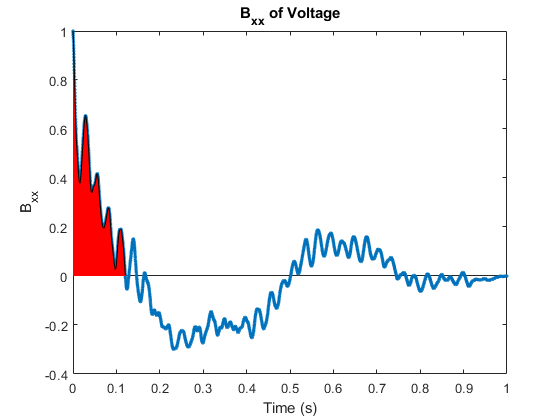

sigma = 0.0075

N = 12.3699

M = 0.5664

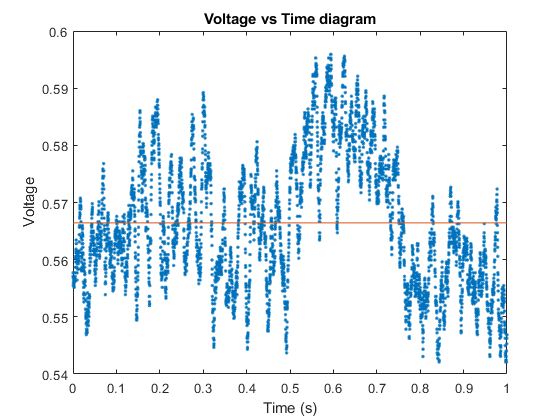

T = 0.0460

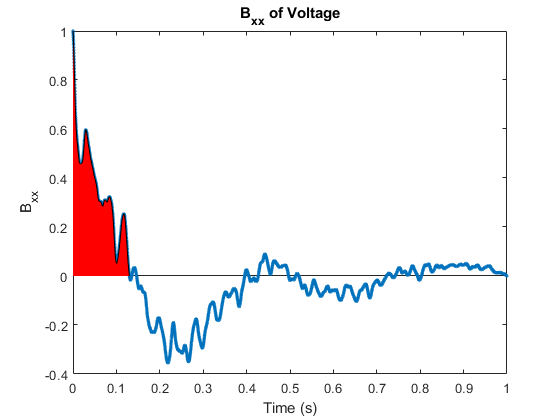

sigma = 0.0082

N = 10.8794

M = 0.5626

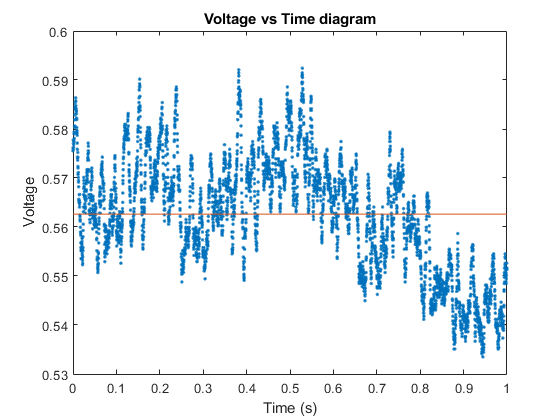

T = 0.0718

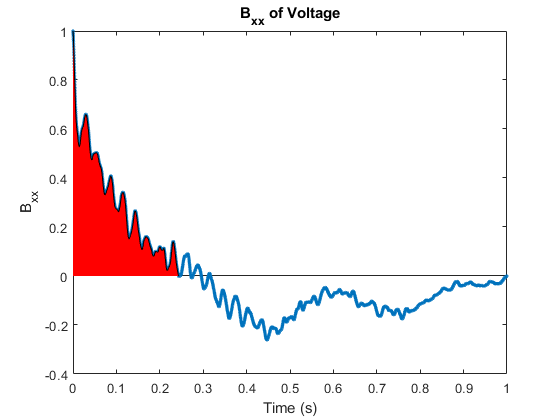

sigma = 0.0084

N = 6.9637

M = 0.5651

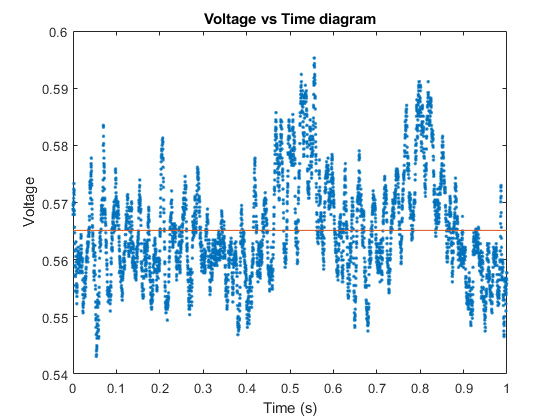

T = 0.0262

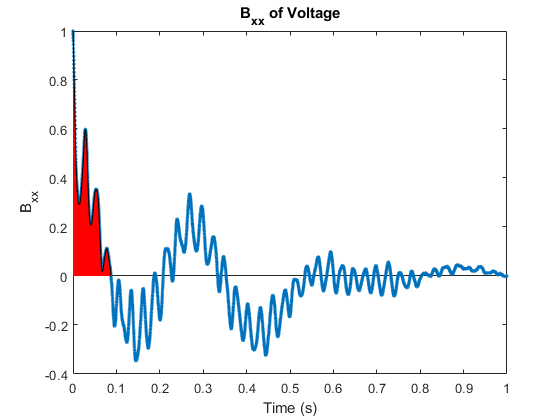

sigma = 0.0064

N = 19.0485



for index = 1:11
    figure
    filename = sprintf(formatspec,idx(1, index));
    load(filename)
    plot(time, data,'.')
    M = mean(data)
    hold on
    plot(time, zeros(1, 5000) + M)
    hold off
    xlabel('Time (s)')
    ylabel('Voltage')
    title('Voltage vs Time diagram')
    s_k = zeros(5000,1);
    for k = 0:4999
        i = 5000 - k;
        t1 = data(1:i) - M;
        t2 = data(1+k:i+k) - M;
        s_k(k+1,1) = dot(t1',t2);    
    end
    var = dot((data - M)', data-M);
    B_xx = s_k ./ var;
    figure
    plot(time, B_xx, '.')
    hold on 
    %These are datapoints so we graph using points
    sum = 0;
    j = 1;
    while B_xx(j)*B_xx(j+1) > 0
        traps = B_xx(j) + B_xx(j+1);
        dt = time(j+1) - time(j);
        sum = sum + dt*traps/2;
        j = j+1;
    end
    time(j);
    T = trapz(time(1:j),B_xx(1:j))
    sum;
    H1=area(time(1:j),B_xx(1:j),'FaceColor',[1 0 0]);
    hold off
    xlabel('Time (s)')
    ylabel('B_{xx}')
    title('B_{xx} of Voltage')
    sigma = sqrt(var/10000)
    N = 1/(2 * T)
    err(index) = 1.96* sigma/sqrt(N);
end

max = max(err)

max = 0.0063